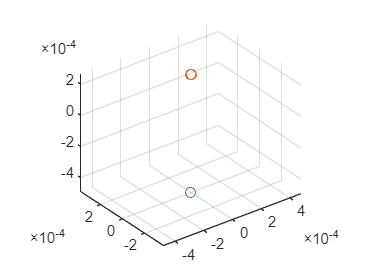

close all;
clearvars;

%   xCenter = f(xCenter)
%   dalpha = -alpha*Df(xCenter)
%   dy <= c*y



syms psym vsym  omegaBsym tauBsym [3 1]
syms Fsym 
syms Asym  [3 3]
Avecsym = reshape(Asym,[],1);
usym = [Fsym; tauBsym];
symvars=[psym; vsym; Avecsym; omegaBsym];
nx = length(symvars);
symvars_ext = [symvars;usym];

varmin = [-0.*ones(3,1); -0.*ones(3,1); -0.*ones(9,1); -0.*ones(3,1)];
varmax = -varmin;
varbounds = [varmin, varmax];
varbounds_init = varbounds;
ubounds = [2; pi/4.*ones(3,1)];
varbounds_ext = [varbounds; [-ubounds, ubounds]];

% L = 1; % arm length
% R = 0.25;
% m = 0.1; % area mass of drone
% I = [2*m*R^2*((L+R/2)^3-(R/2)^3)/3; 2*m*R^2*((L+R/2)^3-(R/2)^3)/3; m*R*(2*L+R)*2*(R/2)^3/3]; % moment of inertia
% M = m*R^2*(2*L+R); % total mass of drone
% J = diag(I); % Inertia Matrix
% g = 9.8;
% 
% niu_v = 0.01;
% niu_w = 0.7;
% 
% syms I [3 1]
% syms M niu_v niu_w
% J = diag(I);

L = 0.127;
I = [0.008513; 0.008513; 0.015579]; % moment of inertia
M = 0.990; % total mass of drone
J = diag(I); % Inertia Matrix
g = 9.8;

niu_v = 0.01;
niu_w = 0.7;

aBsym = 1/M*Fsym.*[0;0;1]; %  Linear acceleration in relation to body

dpsym = vsym;
dvsym = Asym*aBsym+[0;0;-g]-niu_v.*vsym;
dAsym = crossprodmat(omegaBsym)*Asym;
domegaBsym = J\(tauBsym-crossprodmat(omegaBsym)*J*omegaBsym)-niu_w.*omegaBsym;

dAsym_vec = reshape(dAsym,[],1);

dxsym = [dpsym; dvsym; dAsym_vec; domegaBsym];

Df = jacobian(dxsym, symvars);

% Compute point cloud of positions for several values of input (tauB and F norm
% are maxed out)
pnum = 20;
itnum = 1;
Fmax = 15;
tauBnorm_max = pi/4;
%tauB = zeros(3,pnum^2);
%u = zeros(4,pnum^2);
p_cmB = [0;0;0]; % Position of centermass relative to body
p_cm0 = [0;0;0];
v0 = [0;0;0];
omega0B = [0;0;0];
A0 = eye(3);
A0_vec = reshape(A0,[],1);
x0 = [p_cm0; v0; A0_vec; omega0B];

Ts = 0.01;
%x = runge_kutta4(@(y) quadDroneODE(y,[Fmax;tauB],I,M), Ts, x0);

anglemin = 0;
anglemax = 2*pi;
yaw = linspace(anglemin,anglemax,pnum);
tauBnorm = linspace(0, tauBnorm_max, pnum);
%F = linspace(0, Fmax, 2*pnum);
F = [0;Fmax];
u = zeros(4,0);

hold on;
grid on
axis equal
view(3)

kF = 1;
for kF=1:length(F)
    ktau = 1;
    for i=2:pnum
        for j=1:pnum
            tauB(:,ktau) = tauBnorm(i).*[cos(yaw(j)); sin(yaw(j)); 0];
            utau(:,ktau) = [F(kF); tauB(:,ktau)];
            ktau = ktau+1;
        end
    end
    u = [u, utau];
end
state_x = x0.*ones(nx,size(u,2));
for dt=1:itnum
    for ind=1:size(u,2)
        state_x(:,ind) = runge_kutta4(@(y) quadDroneODE(y,u(:,ind),I,M,niu_v,niu_w), Ts, state_x(:,ind));
    end
    %scatter3(state_x(1,:),state_x(2,:),state_x(3,:),'o')
    %display(["Computed instant ", num2str(dt), "/", num2str(itnum)]);

    x = state_x(1,:)';
    y = state_x(2,:)';
    z = state_x(3,:)';

    % % ===v CREDIT: MatJ
    % %   (https://www.mathworks.com/matlabcentral/answers/2038576-fit-ellipsoid-to-x-y-z-data)
    % 
    % [maxval,i]=max(z(:));
    % mu0=[x(i);y(i)];
    % D0=min(z(:));
    % 
    % opts={'FunctionTolerance',1e-14, 'OptimalityTolerance',1e-14, 'StepTolerance',1e-14};
    % G0={D0,maxval-D0,mu0,100*eye(2)};
    % LB={0,0,[],[]};
    % UB={D0,maxval,[],[]};
    % 
    % G = gaussfitn([x(:),y(:)],z(:),G0,LB,UB,opts{:});
    % 
    % %Disaply surfaces
    % [Zg,Ze]=getSurf(x,y,G);
    % 
    % xv = linspace(min(x), max(x), length(x));
    % yv = linspace(min(y), max(y), length(x));
    % [X,Y] = meshgrid(xv, yv);
    % %surf(x,y,z,'FaceAlpha',0.5,'FaceColor','b');
    % mesh(X,Y,Ze,'FaceColor','r', 'FaceAlpha','0.5'); xlabel X, ylabel Y
    % %legend('Raw Data','Fit')
    % 
    % % ===^ CREDIT: MatJ
        
    %pause(Ts);
end

plot_step=size(utau,2);
for k=1:plot_step:size(u,2)
    scatter3(state_x(1,k:k+plot_step-1),state_x(2,k:k+plot_step-1),state_x(3,k:k+plot_step-1),'o')
end


% delta_p = [max(state_x(1,:))-min(state_x(1,:)); max(state_x(2,:))-min(state_x(2,:)); max(state_x(3,:))-min(state_x(3,:))]
% delta_v = [max(state_x(4,:))-min(state_x(4,:)); max(state_x(5,:))-min(state_x(5,:)); max(state_x(6,:))-min(state_x(6,:))]
% delta_A = [max(state_x(7,:))-min(state_x(7,:)) max(state_x(10,:))-min(state_x(10,:)) max(state_x(13,:))-min(state_x(13,:)); 
%            max(state_x(8,:))-min(state_x(8,:)) max(state_x(11,:))-min(state_x(11,:)) max(state_x(14,:))-min(state_x(14,:)); 
%            max(state_x(9,:))-min(state_x(9,:)) max(state_x(12,:))-min(state_x(12,:)) max(state_x(15,:))-min(state_x(15,:))]
% delta_w = [max(state_x(16,:))-min(state_x(16,:)); max(state_x(17,:))-min(state_x(17,:)); max(state_x(18,:))-min(state_x(18,:))]

delta_p = [max(state_x(1,:)); max(state_x(2,:)); max(state_x(3,:))]

delta_p = 1.0e-03 *

    0.0006
    0.0006
    0.2676


delta_v = [max(state_x(4,:)); max(state_x(5,:)); max(state_x(6,:))]

delta_v =     0.0002
    0.0002
    0.0535


delta_A = 1/2.*[max(state_x(7,:))-min(state_x(7,:)) max(state_x(10,:))-min(state_x(10,:)) max(state_x(13,:))-min(state_x(13,:)); 
           max(state_x(8,:))-min(state_x(8,:)) max(state_x(11,:))-min(state_x(11,:)) max(state_x(14,:))-min(state_x(14,:)); 
           max(state_x(9,:))-min(state_x(9,:)) max(state_x(12,:))-min(state_x(12,:)) max(state_x(15,:))-min(state_x(15,:))]

delta_A =     0.0000    0.0000    0.0046
    0.0000    0.0000    0.0046
    0.0046    0.0046    0.0000


delta_w = [max(state_x(16,:)); max(state_x(17,:)); max(state_x(18,:))]

delta_w =     0.9194
    0.9162
    0.0000



% Snap Controller stuff
% Integrate expression for ddF twice
syms A [3 3]
syms F(t) m
syms Kd1 Kd2 Kd3 Kd4 omega dddp_ref ddp_ref dp_ref p_ref v p [3 1]

dF = diff(F);
K1 = diag(Kd1);
K2 = diag(Kd2);
K3 = diag(Kd3);
K4 = diag(Kd4);

kI = [1;0;0];
kB = A*[0;0;1];
ddp = (F*kB-m*g*kI)/m;
dddp = (dF*kB-F*(crossprodmat(omega)*kB))/m;
ddddp_des = -K1*(dddp-dddp_ref)-K2*(ddp-ddp_ref)-K3*(v-dp_ref)-K4*(p-p_ref);
h_F = m*ddddp_des-F*(crossprodmat(omega)*(crossprodmat(omega)*kB))-2*dF*(crossprodmat(omega)*kB)

$$h\_F(t) = \begin{array}{l} \left(\begin{array}{c} F\left(t\right)\,\left(\omega_{2}\,\sigma_{3}+\omega_{3}\,\sigma_{2}\right)+2\,\sigma_{1}\,\frac{\partial }{\partial t}F\left(t\right)+m\,\left({\mathrm{Kd}}_{21}\,\left({\mathrm{ddp}}_{\mathrm{ref1}}+\frac{\frac{49\,m}{5}-A_{1,3}\,F\left(t\right)}{m}\right)+{\mathrm{Kd}}_{31}\,\left({\mathrm{dp}}_{\mathrm{ref1}}-v_{1}\right)-{\mathrm{Kd}}_{41}\,\left(p_{1}-p_{\mathrm{ref1}}\right)+{\mathrm{Kd}}_{11}\,\left({\mathrm{dddp}}_{\mathrm{ref1}}-\frac{A_{1,3}\,\frac{\partial }{\partial t}F\left(t\right)+F\left(t\right)\,\sigma_{1}}{m}\right)\right)\\ m\,\left({\mathrm{Kd}}_{32}\,\left({\mathrm{dp}}_{\mathrm{ref2}}-v_{2}\right)-{\mathrm{Kd}}_{42}\,\left(p_{2}-p_{\mathrm{ref2}}\right)+{\mathrm{Kd}}_{22}\,\left({\mathrm{ddp}}_{\mathrm{ref2}}-\frac{A_{2,3}\,F\left(t\right)}{m}\right)+{\mathrm{Kd}}_{12}\,\left({\mathrm{dddp}}_{\mathrm{ref2}}-\frac{A_{2,3}\,\frac{\partial }{\partial t}F\left(t\right)-F\left(t\right)\,\sigma_{2}}{m}\right)\right)-F\left(t\right)\,\left(\omega_{1}\,\sigma_{3}-\omega_{3}\,\sigma_{1}\right)-2\,\sigma_{2}\,\frac{\partial }{\partial t}F\left(t\right)\\ m\,\left({\mathrm{Kd}}_{33}\,\left({\mathrm{dp}}_{\mathrm{ref3}}-v_{3}\right)-{\mathrm{Kd}}_{43}\,\left(p_{3}-p_{\mathrm{ref3}}\right)+{\mathrm{Kd}}_{23}\,\left({\mathrm{ddp}}_{\mathrm{ref3}}-\frac{A_{3,3}\,F\left(t\right)}{m}\right)+{\mathrm{Kd}}_{13}\,\left({\mathrm{dddp}}_{\mathrm{ref3}}-\frac{A_{3,3}\,\frac{\partial }{\partial t}F\left(t\right)+F\left(t\right)\,\sigma_{3}}{m}\right)\right)-F\left(t\right)\,\left(\omega_{1}\,\sigma_{2}+\omega_{2}\,\sigma_{1}\right)+2\,\sigma_{3}\,\frac{\partial }{\partial t}F\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{2,3}\,\omega_{3}-A_{3,3}\,\omega_{2}\\ \sigma_{2}=A_{1,3}\,\omega_{3}-A_{3,3}\,\omega_{1}\\ \sigma_{3}=A_{1,3}\,\omega_{2}-A_{2,3}\,\omega_{1} \end{array}$$

ddF_des = h_F'*kB;

% Trajectory stuff
syms t ang simT;
sigma = @(t) -20*t^7+70*t^6-84*t^5+35*t^4;
sigma_T = @(t) simT*sigma(t/simT);
r_ang = @(t) [cos(ang*sigma_T(t)); sin(ang*sigma_T(t)); 0.1*sigma_T(t)];

func = r_ang(t)

$$func = \begin{array}{l} \left(\begin{array}{c} \cos\left(\mathrm{ang}\,\mathrm{simT}\,\sigma_{1}\right)\\ \sin\left(\mathrm{ang}\,\mathrm{simT}\,\sigma_{1}\right)\\ \frac{\mathrm{simT}\,\sigma_{1}}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{35\,t^{4}}{{\mathrm{simT}}^{4}}-\frac{84\,t^{5}}{{\mathrm{simT}}^{5}}+\frac{70\,t^{6}}{{\mathrm{simT}}^{6}}-\frac{20\,t^{7}}{{\mathrm{simT}}^{7}} \end{array}$$

dfunc = diff(func)

$$dfunc = \begin{array}{l} \left(\begin{array}{c} -\mathrm{ang}\,\mathrm{simT}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}\\ \mathrm{ang}\,\mathrm{simT}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}\\ \frac{\mathrm{simT}\,\sigma_{1}}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{140\,t^{3}}{{\mathrm{simT}}^{4}}-\frac{420\,t^{4}}{{\mathrm{simT}}^{5}}+\frac{420\,t^{5}}{{\mathrm{simT}}^{6}}-\frac{140\,t^{6}}{{\mathrm{simT}}^{7}}\\ \sigma_{2}=\mathrm{ang}\,\mathrm{simT}\,\left(\frac{35\,t^{4}}{{\mathrm{simT}}^{4}}-\frac{84\,t^{5}}{{\mathrm{simT}}^{5}}+\frac{70\,t^{6}}{{\mathrm{simT}}^{6}}-\frac{20\,t^{7}}{{\mathrm{simT}}^{7}}\right) \end{array}$$

ddfunc = diff(func,2)

$$ddfunc = \begin{array}{l} \left(\begin{array}{c} -\mathrm{ang}\,\mathrm{simT}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}-{\mathrm{ang}}^{2}\,{\mathrm{simT}}^{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{3}\\ \mathrm{ang}\,\mathrm{simT}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}-{\mathrm{ang}}^{2}\,{\mathrm{simT}}^{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{3}\\ \frac{\mathrm{simT}\,\sigma_{1}}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{420\,t^{2}}{{\mathrm{simT}}^{4}}-\frac{1680\,t^{3}}{{\mathrm{simT}}^{5}}+\frac{2100\,t^{4}}{{\mathrm{simT}}^{6}}-\frac{840\,t^{5}}{{\mathrm{simT}}^{7}}\\ \sigma_{2}=\mathrm{ang}\,\mathrm{simT}\,\left(\frac{35\,t^{4}}{{\mathrm{simT}}^{4}}-\frac{84\,t^{5}}{{\mathrm{simT}}^{5}}+\frac{70\,t^{6}}{{\mathrm{simT}}^{6}}-\frac{20\,t^{7}}{{\mathrm{simT}}^{7}}\right)\\ \sigma_{3}={\left(\frac{140\,t^{3}}{{\mathrm{simT}}^{4}}-\frac{420\,t^{4}}{{\mathrm{simT}}^{5}}+\frac{420\,t^{5}}{{\mathrm{simT}}^{6}}-\frac{140\,t^{6}}{{\mathrm{simT}}^{7}}\right)}^{2} \end{array}$$

dddfunc = diff(func,3)

$$dddfunc = \begin{array}{l} \left(\begin{array}{c} \mathrm{ang}\,\mathrm{simT}\,\sin\left(\sigma_{3}\right)\,\sigma_{2}+{\mathrm{ang}}^{3}\,{\mathrm{simT}}^{3}\,\sin\left(\sigma_{3}\right)\,{\sigma_{1}}^{3}-3\,{\mathrm{ang}}^{2}\,{\mathrm{simT}}^{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}\,\sigma_{4}\\ -\mathrm{ang}\,\mathrm{simT}\,\cos\left(\sigma_{3}\right)\,\sigma_{2}-{\mathrm{ang}}^{3}\,{\mathrm{simT}}^{3}\,\cos\left(\sigma_{3}\right)\,{\sigma_{1}}^{3}-3\,{\mathrm{ang}}^{2}\,{\mathrm{simT}}^{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}\,\sigma_{4}\\ -\frac{\mathrm{simT}\,\sigma_{2}}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{140\,t^{3}}{{\mathrm{simT}}^{4}}-\frac{420\,t^{4}}{{\mathrm{simT}}^{5}}+\frac{420\,t^{5}}{{\mathrm{simT}}^{6}}-\frac{140\,t^{6}}{{\mathrm{simT}}^{7}}\\ \sigma_{2}=\frac{5040\,t^{2}}{{\mathrm{simT}}^{5}}-\frac{8400\,t^{3}}{{\mathrm{simT}}^{6}}+\frac{4200\,t^{4}}{{\mathrm{simT}}^{7}}-\frac{840\,t}{{\mathrm{simT}}^{4}}\\ \sigma_{3}=\mathrm{ang}\,\mathrm{simT}\,\left(\frac{35\,t^{4}}{{\mathrm{simT}}^{4}}-\frac{84\,t^{5}}{{\mathrm{simT}}^{5}}+\frac{70\,t^{6}}{{\mathrm{simT}}^{6}}-\frac{20\,t^{7}}{{\mathrm{simT}}^{7}}\right)\\ \sigma_{4}=\frac{420\,t^{2}}{{\mathrm{simT}}^{4}}-\frac{1680\,t^{3}}{{\mathrm{simT}}^{5}}+\frac{2100\,t^{4}}{{\mathrm{simT}}^{6}}-\frac{840\,t^{5}}{{\mathrm{simT}}^{7}} \end{array}$$

% ===v CREDIT: MatJ
%   (https://www.mathworks.com/matlabcentral/answers/2038576-fit-ellipsoid-to-x-y-z-data)
function [Zg,Ze]=getSurf(x,y,G)
    
      [D,A,mu,sig]=deal(G{:});
    
      sz=size(x);
    
      xy=[x(:),y(:)]'-mu;
    
      zg=D+A*exp(-0.5*sum( (sig\xy).*xy,1)); zg=reshape(zg,sz); %Gaussian Fit
     
      ze=D+A*sqrt(1-sum( (sig\xy).*xy)); ze=reshape(ze,sz);   %Ellipsoid Fit

      xv = linspace(min(xy(1,:)), max(xy(1,:)), sz(1));
      yv = linspace(min(xy(2,:)), max(xy(2,:)), sz(1));
      [X,Y] = meshgrid(xv, yv);
      Zg = griddata(x,y,zg,X,Y);
      Ze = griddata(x,y,ze,X,Y);

    
end
% ===^ CREDIT: MatJ


%scatter3(tauB(1,:),tauB(2,:),tauB(3,:))
%scatter3(x(1,:),x(2,:),x(3,:))

return

% Using Yalmip %
options = sdpsettings('verbose',1,'solver','fmincon','debug',1);

% u = sdpvar(size(A,1)*ones(1,1),ones(1,1));
% delta = sdpvar(ones(1,1),ones(1,1));
% 
% J = @(u,x,delta) 1/2*norm(u)^2 + rho*delta^2;
% constraints = @(x,u,delta) [LfV(x) + LgV(x)*u + delta <= -gamma*V(x);
%                             Lfh(x) + Lgh(x)*u >= -alpha*h(x);
%                             norm(u) <= max_unorm]';

%Omega = sdpvar(repmat(4,1,size(state_x,2)),ones(1,size(state_x,2)));
nx = 3;
Omega = diag(sdpvar(1,nx,'full','real'));

objective = 0;
%constraints = @(Omega) [min(Omega)^-1/2 <= 1];
constraints =  @(x) [];
Phi = @(x) x.^2;
%J = @(dj) norm(dj-(Omega*Phi(dj))^-1/2*dj)^2;
J = @(dj) norm(dj-((dj'*Omega*dj)^-1/2)*dj)^2;
for k=1:size(state_x,2)
    objective = objective + J(state_x(1:nx,k));
end
%optimize(constraints(x(:,k),u,delta),J(u,x(:,k),delta),options);
res=optimize(constraints(Omega), objective, options);
%value(Omega)

return

% 
out1 = cell(size(Df));
range_vec = zeros(1,2); % Contains range intervals of non-constant elements in Df
% Organized in column order of Df
constDfMx = zeros(size(Df)); % Build matrix with constant elements of Df

ind = 1;
for j=1:size(Df,2)
    for i=1:size(Df,1)
        %out1 = getMonotoneElements(Df(i,j),out1);
        if hasSymType(Df(i,j),"variable")
            A = getElements(Df(i,j),symvars_ext,varbounds_ext);
            out1(i,j) = {A.r};
            range_vec(ind,:) = A.r;
            ind = ind+1;
        else
            constDfMx(i,j) = double(Df(i,j));
            out1(i,j) = {double(Df(i,j))};
        end
    end
end
out1;
range_vec;
constDfMx;

hasVarMx = hasSymType(Df,"variable");
dim = size(hasVarMx,1);
nvar = size(range_vec,1);
%IMJ = cell(1,2^nvar);
c = -inf;
while true
  A = rand(dim, dim);
  if rank(A) == dim; break; end    %will be true nearly all the time
end
alph = A' * A;
Dfxo = double(subs(Df,symvars_ext,[x_init; 1; [0.5;0;0]]));
tic;
for k=1:2^nvar-1
    Mi = constDfMx;
    code = str2num(dec2bin(k-1,nvar)')+1;
    ind = 1;
    for j=1:size(Mi,2)
        for i=1:size(Mi,1)
            if hasVarMx(i,j)==1
                Mi(i,j) = range_vec(ind,code(ind));
                ind=ind+1;
            end
        end
    end
    c = max(c,max(eig((alph*(Mi-Dfxo)/alph)'+(alph*(Mi-Dfxo)/alph))));
    disp(['Iteration ', num2str(k), ' of ', num2str(2^nvar)]);
    %Mi
    %IMJ{k} = Mi;
end
toc
